# **demo12 of Im2mesh package**

demo12 - Demonstrate function pixelMesh (pixel-based quadrilateral mesh)

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

## pixelMesh

pixelMesh is a function used to generate pixel-based quadrilateral mesh. It’s written by me many years ago. It’s for some special applications.

Let's start demo. First, we'll use function pixelMesh to generate mesh. In the next step, we'll export the mesh.

Import image Circle.tif.

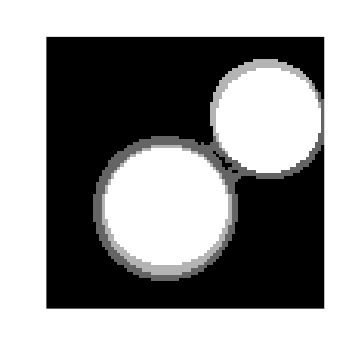

im = imread('Circle.tif');
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

Generate mesh.

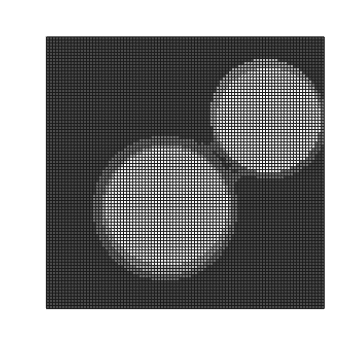

[ vert, quad, tnum, vert2, quad2 ] = pixelMesh( im );
plotMeshes( vert, quad, tnum )

Zoom in.

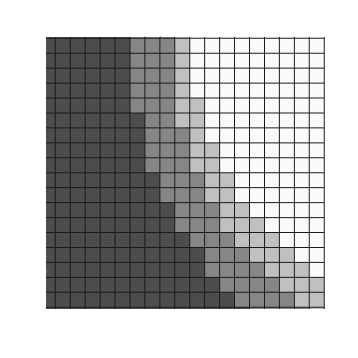

plotMeshes( vert, quad, tnum )
xlim([9.9 28.5])
ylim([15.4 33.6])

## Phase selection before meshing

The syntax of function pixelMesh is similar to function im2mesh. We can specify phase selection before meshing

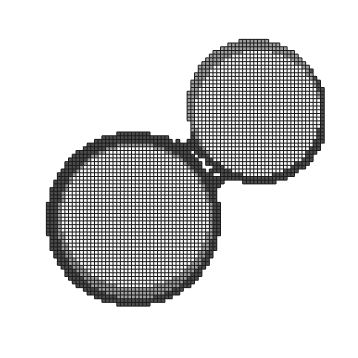

opt.select_phase = [2 3 4];
[ vert, quad, tnum, vert2, quad2 ] = pixelMesh( im, opt );
plotMeshes( vert, quad, tnum )

Zoom in.

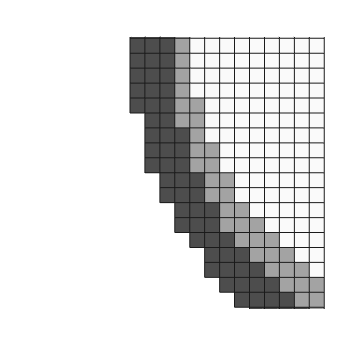

plotMeshes( vert, quad, tnum )
xlim([9.9 28.5])
ylim([15.4 33.6])

## Outputs of pixelMesh

vert is mesh nodes (for linear element)

quad is mesh elements (for linear element)

tnum is label of phase

vert2 is mesh nodes (for quadratic element)

quad2 is mesh elements (for quadratic element)

## Prepare for mesh export

Setup parameters.

% parameters for mesh export
dx = 1; dy = 1;     % scale of your imgage
precision_nodecoor = 8;

Scale node coordinates according to dx and dy.

% scale node coordinates of linear elements
vert( :, 1 ) = vert( :, 1 ) * dx;
vert( :, 2 ) = vert( :, 2 ) * dy;

% scale node coordinates of quadratic elements
vert2( :, 1 ) = vert2( :, 1 ) * dx;
vert2( :, 2 ) = vert2( :, 2 ) * dy;

## Reorgnize nodes and elements

We use function getNodeEle to reorganize node coordinates and elements from the mesh, and add node numbering and element numbering.

% for linear element
[ nodecoor_list, nodecoor_cell, ele_cell ] = getNodeEle( vert, quad, tnum );

We can do the same operation to quadratic elements using the same function.

% for quadratic element
[ nodecoor_list_Q, nodecoor_cell_Q, ele_cell_Q ] = getNodeEle( vert2, quad2, tnum );

## Export mesh as bdf file (Nastran bulk data)

We use function printBdf to do that. The bdf file 'test.bdf' will be saved to current folder.

printBdf( nodecoor_list, ele_cell, precision_nodecoor );

printBdf Done! Check the bdf file!


We can explictly specify the file name.

file_name = 'test_2025.bdf';
printBdf( nodecoor_list, ele_cell, precision_nodecoor, file_name );

printBdf Done! Check the bdf file!


## Export mesh as inp file (Abaqus)

Here, we use function printInp_multiSect to save multiple phases in the mesh as multiple sections. 

The exported inp file would have a model with one part, which contains multiple sections. Each section corresponds to one phase in your image.

### Linear element

Before exporting mesh, we specify element type.

ele_type = 'CPS4';

We use function printInp_multiSect to save multiple phases in the mesh as multiple sections. The inp file will be saved to current folder.

file_name = 'test_linear.inp';
printInp_multiSect( nodecoor_list, ele_cell, ele_type, precision_nodecoor, file_name );

printInp_multiSect Done! Check the inp file!


### Quadratic element

We can do the same operation to quadratic elements. 

ele_type_Q = 'CPS8';

To avoid confusion, you can explictly specify the file name.

file_name = 'test_quadratic.inp';
printInp_multiSect( nodecoor_list_Q, ele_cell_Q, ele_type_Q, precision_nodecoor, file_name );

printInp_multiSect Done! Check the inp file!


## Comments

You will find that when exporting mesh, the functions for triangular and quadrilateral mesh is the same. That's very convenient.

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo